% # 1 a
syms x
f = x^5 + 4*x^4 - 2*x^3-14*x^2-3*x-18 

$$f = x^{5}+4\,x^{4}-2\,x^{3}-14\,x^{2}-3\,x-18$$

factor(f)

$$ans = \left(\begin{array}{cccc} x-2 & x^{2}+1 & x+3 & x+3 \end{array}\right)$$

% # 2.1
syms x
f = x*exp(-x)

$$f = x\,{\mathrm{e}}^{-x}$$

limit(f, inf)

$$ans = 0$$

% # 3.2
syms x
f = 3*x^4-14*x^3+12*x^2+24*x+6

$$f = 3\,x^{4}-14\,x^{3}+12\,x^{2}+24\,x+6$$

simplify(diff(f))

$$ans = 6\,\left(2\,x+1\right)\,{\left(x-2\right)}^{2}$$

% # 4.2
syms x
f = 1/(sin(x))^3

$$f = \frac{1}{{\sin\left(x\right)}^{3}}$$

int(f, x)

$$ans = \frac{\log\left(\tan\left(\frac{x}{2}\right)\right)}{2}-\frac{\cos\left(x\right)}{2\,{\sin\left(x\right)}^{2}}$$

% 5.1
syms k
symsum(1/k^2, k)

$$ans = \left\{ \begin{array}{cl} -\psi^{\prime }(k) & \text{ if }0<k\\ \psi^{\prime }(1-k) & \text{ if }k\leq 0 \end{array}\right.$$

% 6.2
syms x
f = exp(x)

$$f = {\mathrm{e}}^{x}$$

a = 0; n = 5;
taylor(f,x ,a, 'Order', n)

$$ans = \frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

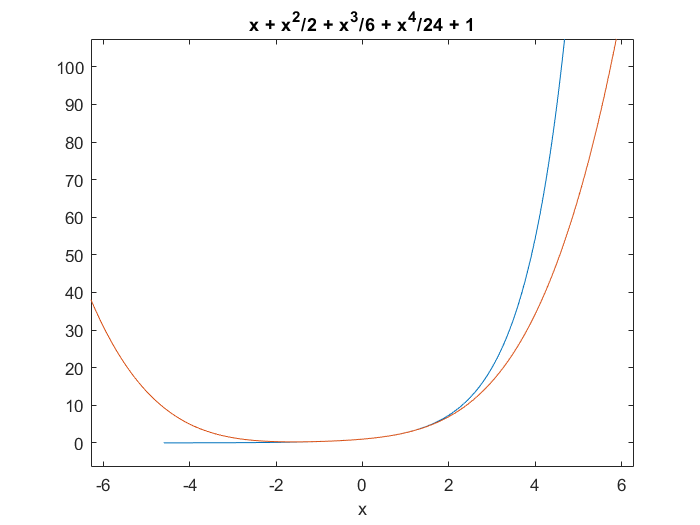

ezplot(f)
hold on;
ezplot(taylor(f,x ,a, 'Order', n))

% 7
syms x
f = exp(1/(1-x^2))/(1+x^2)

$$f = \frac{{\mathrm{e}}^{-\frac{1}{x^{2}-1}}}{x^{2}+1}$$

k = limit(f/x, inf)

$$k = 0$$

b = limit(f-k*x, inf)

$$b = 0$$

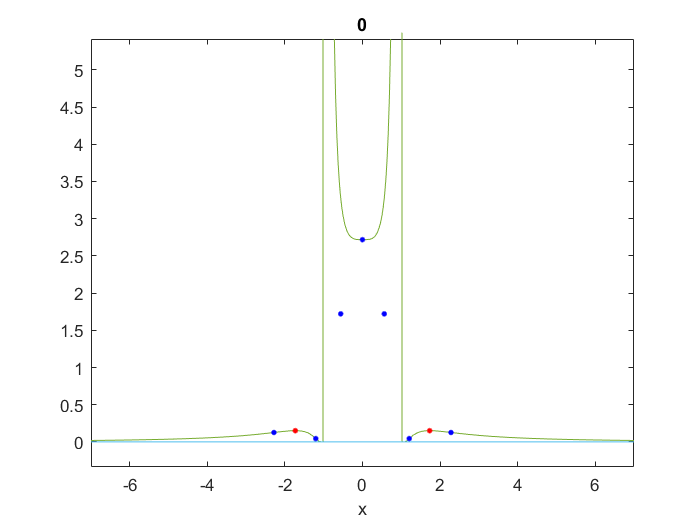

ezplot(f, -7, 7)
hold on
ezplot(k*x+b,-7, 7)
hold on
extrem = solve(diff(f));
value = subs(f, x, extrem);
for i = 1:length(extrem)
    plot(extrem(i), value(i), ".", "MarkerSize", 10, "Color", "red")
    hold on
end
extrem = solve(diff(diff(f)));
value = subs(f, x, extrem);
for i = 1:length(extrem)
    if (imag(value(i)) == 0)
          plot(extrem(i), value(i), ".", "MarkerSize", 10, "Color", "blue")
    hold on  
    end
end

% 8 
syms x
f = sin(x)/(x^2+1);
hold on
ezplot(f,[-5 5])
y1 = matlabFunction(f);
y2 = matlabFunction(-f);
[min_x1, min_y1] = fminbnd(y1,-5,5)

min_x1 = -0.7980

min_y1 = -0.4374

[min_x2, min_y2] = fminbnd(y2,-5,5)

min_x2 = 0.7980

min_y2 = -0.4374

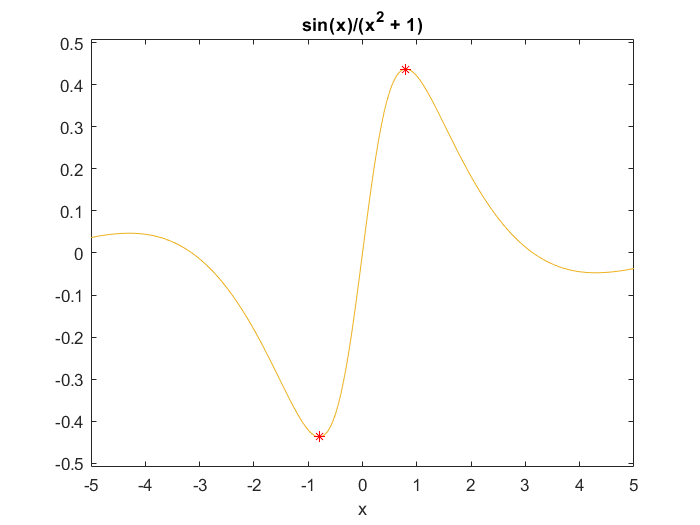

plot(min_x1, min_y1,'r*');
plot(min_x2, -min_y2,'r*');
hold off

% 9
syms u
syms t
x = t*cos(u)*cos(u);
y = t^2*cos(u)*sin(u);
z = t^3 * sin(u);
up =  (det([diff(y, u), diff(z); diff(diff(y)), diff(diff(z))]))^2 + (det([diff(x), diff(z); diff(diff(x)), diff(diff(z))]))^2 + (det([diff(x), diff(y); diff(diff(x)), diff(diff(y))]))^2;
down = ((diff(x))^2+(diff(y))^2+(diff(z))^2)^3;
k = sqrt(up/down)

$$k = \begin{array}{l} \sqrt{\frac{4\,{\cos\left(u\right)}^{6}+{\left(3\,{\cos\left(u\right)}^{2}\,\sin\left(u\right)+{\sin\left(u\right)}^{3}\right)}^{2}+{\left(2\,{\cos\left(u\right)}^{4}+\sigma_{1}+2\,{\sin\left(u\right)}^{4}\right)}^{2}}{{\left({\cos\left(u\right)}^{2}+{\left({\cos\left(u\right)}^{2}-{\sin\left(u\right)}^{2}\right)}^{2}+\sigma_{1}\right)}^{3}}}\\ \mathrm{where}\\ \sigma_{1}=4\,{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2} \end{array}$$

down = up;
up = det([diff(x) diff(y) diff(z); diff(diff(x)) diff(diff(y)) diff(diff(z)); diff(diff(diff(x))) diff(diff(diff(y))) diff(diff(diff(z))) ])

$$up = 6\,{\cos\left(u\right)}^{5}+12\,{\cos\left(u\right)}^{3}\,{\sin\left(u\right)}^{2}+6\,\cos\left(u\right)\,{\sin\left(u\right)}^{4}$$

kr = up/down

$$kr = \frac{6\,{\cos\left(u\right)}^{5}+12\,{\cos\left(u\right)}^{3}\,{\sin\left(u\right)}^{2}+6\,\cos\left(u\right)\,{\sin\left(u\right)}^{4}}{4\,{\cos\left(u\right)}^{6}+{\left(3\,{\cos\left(u\right)}^{2}\,\sin\left(u\right)+{\sin\left(u\right)}^{3}\right)}^{2}+{\left(2\,{\cos\left(u\right)}^{4}+4\,{\cos\left(u\right)}^{2}\,{\sin\left(u\right)}^{2}+2\,{\sin\left(u\right)}^{4}\right)}^{2}}$$